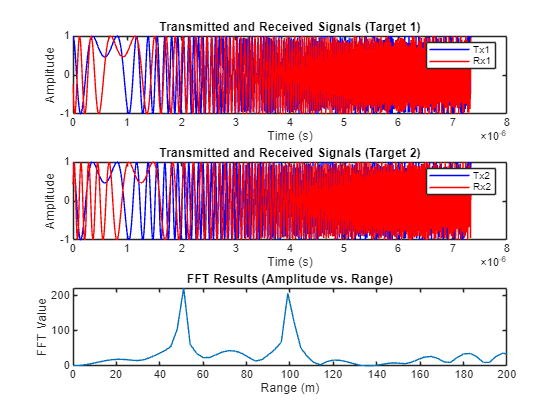

% Radar Parameters
c = 3e8; % Speed of light (m/s)
R1 = 50; % Distance to the first target (m)
R2 = 100; % Distance to the second target (m)
Tsweep = 5.5; % Sweep time (s)
Nr = 1024; % Number of samples
Range_max = 200; % Maximum range (m)

% User-defined Bandwidth Value
B = 50e6; % Bandwidth (Hz) (e.g., can be adjusted with a slider)
range_res = c / (2 * B); % Range resolution
Tchirp = Tsweep * (2 * Range_max / c); % Sweep duration
slope = B / Tchirp; % Chirp slope
fc = 77e9; % Carrier frequency (Hz)

% Time Vector
t = linspace(0, Tchirp, Nr);

% Time Delays
td1 = 2 * R1 / c;
td2 = 2 * R2 / c;

% Signal Generation
Tx1 = cos(2 * pi * (fc * t + slope * t.^2 / 2)); % Transmitted signal (target 1)
Rx1 = cos(2 * pi * (fc * (t - td1) + slope * (t - td1).^2 / 2)); % Received signal (target 1)

Tx2 = cos(2 * pi * (fc * t + slope * t.^2 / 2)); % Transmitted signal (target 2)
Rx2 = cos(2 * pi * (fc * (t - td2) + slope * (t - td2).^2 / 2)); % Received signal (target 2)

% Mixing
Mix1 = Tx1 .* Rx1;
Mix2 = Tx2 .* Rx2;
Mix = Mix1 + Mix2;

% FFT Processing
FFT_mix = fft(Mix);
FFT_single_side_mix = abs(FFT_mix(1:Nr/2)); % Single-sided FFT
range_values = (0:(Nr/2)-1) * range_res; % Distance values

% Plotting the Results
figure;

% Transmitted and Received Signals (Target 1)
subplot(3,1,1);
plot(t, Tx1, 'b'); hold on;
plot(t, Rx1, 'r');
title('Transmitted and Received Signals (Target 1)');
xlabel('Time (s)'); ylabel('Amplitude');
legend('Tx1', 'Rx1');

% Transmitted and Received Signals (Target 2)
subplot(3,1,2);
plot(t, Tx2, 'b'); hold on;
plot(t, Rx2, 'r');
title('Transmitted and Received Signals (Target 2)');
xlabel('Time (s)'); ylabel('Amplitude');
legend('Tx2', 'Rx2');

% FFT Results (Amplitude vs. Range)
subplot(3,1,3);
plot(range_values, FFT_single_side_mix);
title('FFT Results (Amplitude vs. Range)');
xlabel('Range (m)'); ylabel('FFT Value');
xlim([0 Range_max]);